%% Text Size
set(0,'DefaultAxesFontsize',10);
set(0,'DefaultTextFontsize',10);
% set(0,'DefaultAxesFontWeight','bold');
% set(0,'DefaultTextFontWeight','bold');

%% Text Fonts
% set(0,'DefaultTextFontname','Arial')
% set(0,'DefaultAxesFontname','Arial')
set(0,'DefaultTextFontname','Times New Roman');
set(0,'DefaultAxesFontname','Times New Roman');

clear;

datalist = ["Behavior_and_states_l`.mat" ...
    "Behavior_and_states_l``.mat" ...
    "Behavior_and_states_l``1.mat" ...
    "Behavior_and_states_l``2.mat" ...
    "Behavior_and_states_l``3.mat" ...
    "Behavior_and_states_l``4.mat" ...
    "Behavior_and_states_l``5.mat" ...
    "Behavior_and_states_l``6.mat" ...
    "Behavior_and_states_l``7.mat" ...
    "Behavior_and_states_l``11.mat"];

% datalist = "Behavior_and_states_exp.mat";

behavior_count = zeros(7,1);
state_count = zeros(6,1);
state_in_behavior_count = zeros(6,7);

seqcounts = cell(7,1);
for i = 1:7
    seqcounts{i} = zeros(6);
end

[m2, n2] = size(datalist);

for j = 1:n2
    
    load(datalist(j));
    [m,n] = size(behaviors);
    
    for i = 1:m
        behavior_count(behaviors(i)) = behavior_count(behaviors(i)) + 1;
        state_count(classes(i)) = state_count(classes(i)) + 1;
        state_in_behavior_count(classes(i),behaviors(i)) = state_in_behavior_count(classes(i),behaviors(i)) + 1;
    end
    
    i = 1;
    while i <= m
        index = behaviors(i);
        
        left = i;
        k = i + 1;
        right = i;
        while k <= m
            if behaviors(k) == index
                right = k;
            else
                break;
            end
            k = k + 1;
        end
        
        class_array = classes(left:right);
        
        for j = 1:6
            for k = 1:6
                seqcounts{index}(j,k) = seqcounts{index}(j,k) + sum(strfind(class_array, [j k])~=0);
            end
        end
        
        i = right + 1;
    end

end

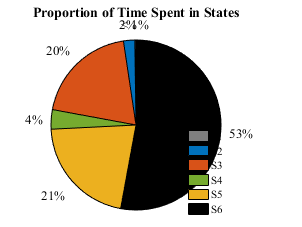

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',[5,5,8,6]);
set(gca,'Position', [0 0 0.9 0.9]);

piecolourmap = [[0.5 0.5 0.5]; [0 0.4470 0.7410]; [0.8500 0.3250 0.0980]; ...
    [0.4660 0.6740 0.1880]; [0.9290 0.6940 0.1250]; [0 0 0]];

p2 = pie(state_count);
colormap(piecolourmap);
title('Proportion of Time Spent in States');
labels = {'S1', 'S2', 'S3', 'S4', 'S5', 'S6'};
leg = legend(labels,'Location','southeast');
legend('boxoff');
leg.ItemTokenSize = [15 15];

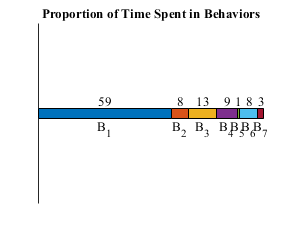

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',[5,5,8,6]);
set(gca,'Position', [0.125 0.1 0.75 0.8]);

proportion = behavior_count/sum(behavior_count);

ba = barh(1,proportion'.*100, 0.1, 'stacked');
hold on;

behavior_list = ['B_1'; 'B_2'; 'B_3'; 'B_4'; 'B_5'; 'B_6'; 'B_7'];

for i = 1:7
    xtips = ba(i).XEndPoints;
    ytips = ba(i).YEndPoints;
    if i == 1
        ytips_previous = ytips*0;
    else
        ytips_previous = ba(i-1).YEndPoints;
    end
    
    ytips = (ytips + ytips_previous)/2;
    data = round(ba(i).YData);

    text_data = num2str(data);
    text(ytips,xtips+0.12,text_data,'HorizontalAlignment','center',...
        'VerticalAlignment','middle');
    text(ytips,xtips-0.15,behavior_list(i,:),'HorizontalAlignment','center',...
        'VerticalAlignment','middle');
end

title('Proportion of Time Spent in Behaviors');

axis off;

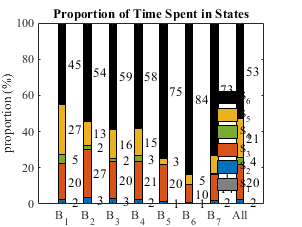

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',[5,5,8,6]);
set(gca,'Position', [0.125 0.1 0.75 0.8]);

proportion = zeros(6,8);

for i = 1:7
    proportion(:,i) = state_in_behavior_count(:,i)/sum(state_in_behavior_count(:,i));
end
proportion(:,8) = state_count/sum(state_count);

% X = categorical({'Small','Medium','Large','Extra Large'});
% X = reordercats(X,{'Small','Medium','Large','Extra Large'});
% 
% x = ['B_1'; 'B_2'; 'B_3'; 'B_4'; 'B_5'; 'B_6'; 'B_7'; 'All'];

ba = bar(proportion'.*100, 0.3, 'stacked', "FaceColor", "flat");
hold on;
for i = 1:6
    ba(i).CData = piecolourmap(i,:);
end

h = get(gca,'Children');
labels = {'S_6', 'S_5', 'S_4', 'S_3', 'S_2', 'S_1'};
leg = legend([h(1) h(2) h(3) h(4) h(5) h(6)], labels,'Location','southeast');
legend('boxoff');
leg.ItemTokenSize = [15 15];

for i = 2:6
    xtips = ba(i).XEndPoints;
    ytips = ba(i).YEndPoints;
    ytips_previous = ba(i-1).YEndPoints;
    ytips = (ytips + ytips_previous)/2;
    datas = round(ba(i).YData);
    for j = 1:8
        if datas(j) >= 1
            text_data = num2str(datas(j));
            text(xtips(j)+0.5,ytips(j),text_data,'HorizontalAlignment','center',...
                'VerticalAlignment','middle');
        end
    end
end

title('Proportion of Time Spent in States');
xticklabels({'B_1', 'B_2', 'B_3', 'B_4', 'B_5', 'B_6', 'B_7', 'All'});
ylabel('proportion (%)');

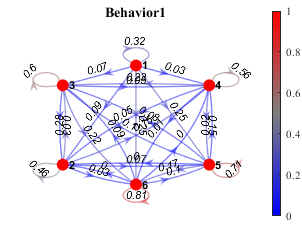

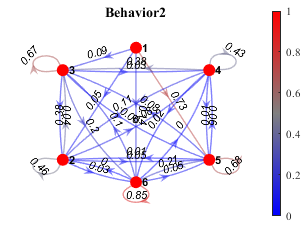

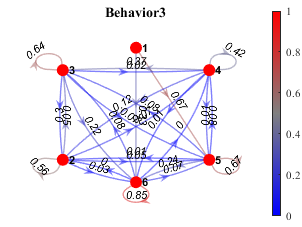

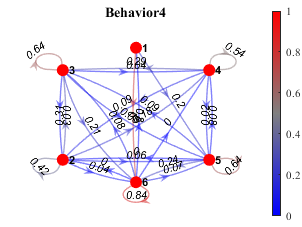

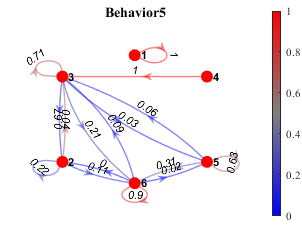

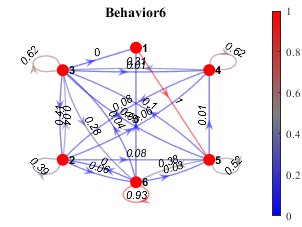

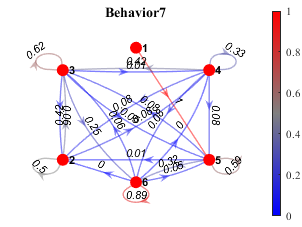

for i = 1:7
    
    if ~sum(sum(seqcounts{i}))>0
        continue;
    end
    for j = 1:6
        if ~sum(seqcounts{i}(j,:))>0 && ~sum(seqcounts{i}(:,j))>0
            seqcounts{i}(j,j) = 1;
        end
    end
    
    figure('Color',[1 1 1]);
    set(gcf,'unit','centimeters','position',[5,5,8,6]);
    set(gca,'Position', [0 0 0.9 0.9]);
    
    markovchain = dtmc(seqcounts{i});
    stateNames = ["1" "2" "3" "4" "5" "6"];
    markovchain.StateNames = stateNames;
    gp = graphplot(markovchain, 'ColorEdges', true, 'LabelEdges', true);
    gp.XData = [0, -1, -1, 1, 1, 0];
    gp.YData = [1.5, -1, 1, 1, -1, -1.5];
    gp.EdgeFontSize = 8;
    gp.ArrowPosition = 0.45;
    gp.ArrowSize = 8;
%     gp.EdgeLabelMode = "auto";
%     edgelabel = gp.EdgeLabel;
    
    cb = colorbar();
    colormap(bluegrayred);
    cb.Position = [0.9, 0.05, 0.03, 0.9];
    title(['Behavior' num2str(i)]);
    
end

% figure('Color',[1 1 1]);
% set(gcf,'unit','centimeters','position',[5,5,16,12]);
% set(gca,'Position', [0 0 1 1]);
% 
% minus = 0;
% for i = 1:7
%     
%     if ~sum(sum(seqcounts{i}))>0
%         minus = minus + 1;
%         continue;
%     end
%     
%     for j = 1:6
%         if ~sum(seqcounts{i}(j,:))>0 && ~sum(seqcounts{i}(:,j))>0
%             seqcounts{i}(j,j) = 1;
%         end
%     end
%     
%     subplot(2,3,i-minus);
%     markovchain = dtmc(seqcounts{i});
%     stateNames = ["1" "2" "3" "4" "5" "6"];
%     markovchain.StateNames = stateNames;
%     gp = graphplot(markovchain, 'ColorEdges', true, 'LabelEdges', true);
%     gp.XData = [0, -1, -1, 1, 1, 0];
%     gp.YData = [1.5, -1, 1, 1, -1, -1.5];
%     gp.EdgeFontSize = 8;
%     gp.ArrowPosition = 0.45;
%     gp.ArrowSize = 8;
% %     gp.EdgeLabelMode = "auto";
% %     edgelabel = gp.EdgeLabel;
%     
%     colorbar("off");
%     colormap(bluegrayred);
% %     cb.Position = [0.9, 0.05, 0.03, 0.9];
%     title(['Behavior' num2str(i)]);
%     
% end

function h = hot2(m)
%HOT    Red-yellow-white color map inspired by black body radiation
%   HOT(M) returns an M-by-3 matrix containing a "hot" colormap.
%   HOT, by itself, is the same length as the current figure's
%   colormap. If no figure exists, MATLAB uses the length of the
%   default colormap.
%
%   For example, to reset the colormap of the current figure:
%
%             colormap(hot)
%
%   See also HSV, PARULA, GRAY, PINK, COOL, BONE, COPPER, FLAG, 
%   COLORMAP, RGBPLOT.

%   C. Moler, 8-17-88, 5-11-91, 8-19-92.
%   Copyright 1984-2015 The MathWorks, Inc.

if nargin < 1
   f = get(groot,'CurrentFigure');
   if isempty(f)
      m = size(get(groot,'DefaultFigureColormap'),1);
   else
      m = size(f.Colormap,1);
   end
end

n = fix(3/8*m);

r = 0.8*[(1:n)'/n; ones(m-n,1)];
g = 0.8*[zeros(n,1); (1:n)'/n; ones(m-2*n,1)];
b = 0.8*[zeros(2*n,1); (1:m-2*n)'/(m-2*n)];

h = [r g b];
end


function c = bluegrayred(m)

if nargin < 1
    m = size(get(gcf,'colormap'),1); 
end

% r = 0.3*(0:m-1)'/max(m-1,1);
% r = 0.7 + r;
% g = 0.7*(0:m-1)'/max(m-1,1);
% g = flipud(g);
% b = g;

% 0,0,1 - 0.5,0.5,0.5 - 1,0,0

if (mod(m,2) == 0)
    m1 = m*0.5;
    r = 0.5*(0:m1-1)'/max(m1-1,1);
    g = r;
    r = [r; 0.5+r];
    g = [g; flipud(g)];
    b = flipud(r);
else
    m1 = floor(m*0.5);
    r = 0.5*(0:m1-1)'/max(m1,1);
    g = r;
    r = [r; 0.5; 0.5+r];
    g = [g; 0.5; flipud(g)];
    b = flipud(r);
end

c = [r g b]; 
end

function c = grayred(m)

if nargin < 1
    m = size(get(gcf,'colormap'),1); 
end

r = 0.5*(0:m-1)'/max(m-1,1);
g = flipud(r);
b = g;
r = 0.5 + r;

c = [r g b]; 
end

function c = grayblue(m)

if nargin < 1
    m = size(get(gcf,'colormap'),1); 
end

r = 0.5*(0:m-1)'/max(m-1,1);
g = flipud(r);
b = g;
r = 0.5 + r;

c = [r g b]; 
end